## Fruit recognition validation from the book

clc
clear all

% Load input data and target values
input_data = readmatrix('validation/input_p.txt');

Error using readmatrix (line 171)
Unable to find or open 'validation/input_p.txt'. Check the path and filename or file permissions.

target_data = readmatrix('validation/target_t.txt');

% Format data into prototypes 
prototypes = cell(size(input_data, 1), 1);
for i = 1:size(input_data, 1)
    prototypes{i} = {input_data(i, :)', target_data(i, :)'};
end

% Hyperparameters
input_size = size(input_data, 2); % Number of classes
max_epochs = 100; % Maximum number of epochs
learning_rate = 0.2; % Delta value

% Create and train the ADALINE network
stop_code = 0;
ntry = 0;
number_of_retries = 1; % If training faill retry n times
validation_adaline = adalineNetwork(input_size, 'classification'); % Set for classification
while (stop_code ~= 1 && ntry < number_of_retries)
    [validation_adaline, stop_code] = validation_adaline.train(prototypes, max_epochs, learning_rate);
    ntry = ntry + 1;
end

% Save final weights and bias to files
w_file = 'validation/w.txt';
b_file = 'validation/b.txt';

% Write weights & bias to file
writematrix(validation_adaline.Weights, w_file, 'Delimiter', 'tab');
writematrix(validation_adaline.Bias, b_file, 'Delimiter', 'tab');

disp('Mode:');
disp(validation_adaline.Mode);
disp('Weights:');
disp(validation_adaline.Weights);
disp('Bias:');
disp(validation_adaline.Bias);

validation_adaline.classify(input_data(1,:)') % -1 Orange 
validation_adaline.classify(input_data(2,:)') % 1 Apple

## Example 1 classification 2 classes

#### From book P10.2

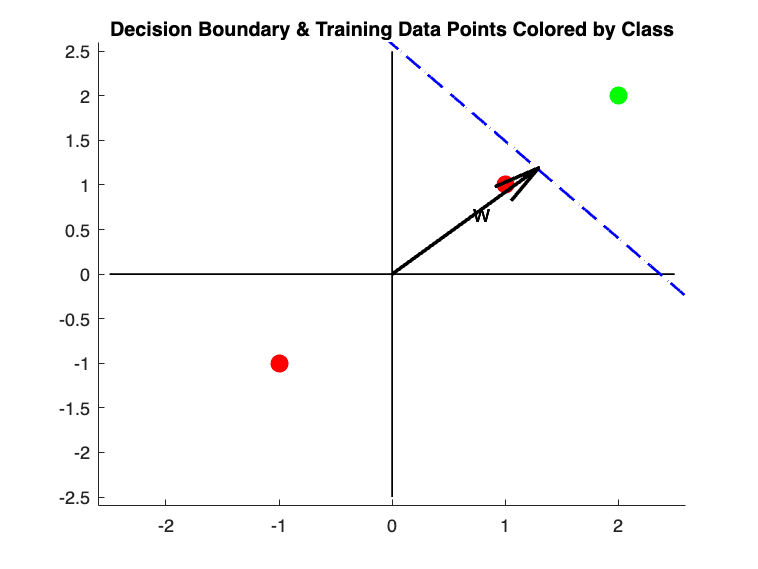

Training completed successfully in 5 epochs.


clc
clear all

% Load input data and target values
input_data = readmatrix('c1/input_p.txt');
target_data = readmatrix('c1/target_t.txt'); 

% Format data into prototypes 
prototypes = cell(size(input_data, 1), 1);
for i = 1:size(input_data, 1)
    prototypes{i} = {input_data(i, :)', target_data(i, :)'};
end

% Hyperparameters
input_size = size(input_data, 2); % Number of classes
max_epochs = 100; % Maximum number of epochs
learning_rate = 0.3; % Delta value

% Create and train the ADALINE network
stop_code = 0;
ntry = 0;
number_of_retries = 1; % If training faill retry n times
c1_adaline = adalineNetwork(input_size, 'classification'); % Set for classification
while (stop_code ~= 1 && ntry < number_of_retries)
    [c1_adaline, stop_code] = c1_adaline.train(prototypes, max_epochs, learning_rate);
    ntry = ntry + 1;
end


% Save final weights and bias to files
w_file = 'c1/w.txt';
b_file = 'c1/b.txt';

% Write weights & bias to file
writematrix(c1_adaline.Weights, w_file, 'Delimiter', 'tab');
writematrix(c1_adaline.Bias, b_file, 'Delimiter', 'tab');

disp('Mode:');

Mode:


disp(c1_adaline.Mode);

classification


disp('Weights:');

Weights:


disp(c1_adaline.Weights);

    1.4399    1.3233



disp('Bias:');

Bias:


disp(c1_adaline.Bias);

   -3.4161




c1_adaline.classify(input_data(1,:)') % -1 

ans = -1

c1_adaline.classify(input_data(2,:)') % -1 

ans = -1

c1_adaline.classify(input_data(3,:)') % 1

ans = 1

## Example 2 classification 2 classes

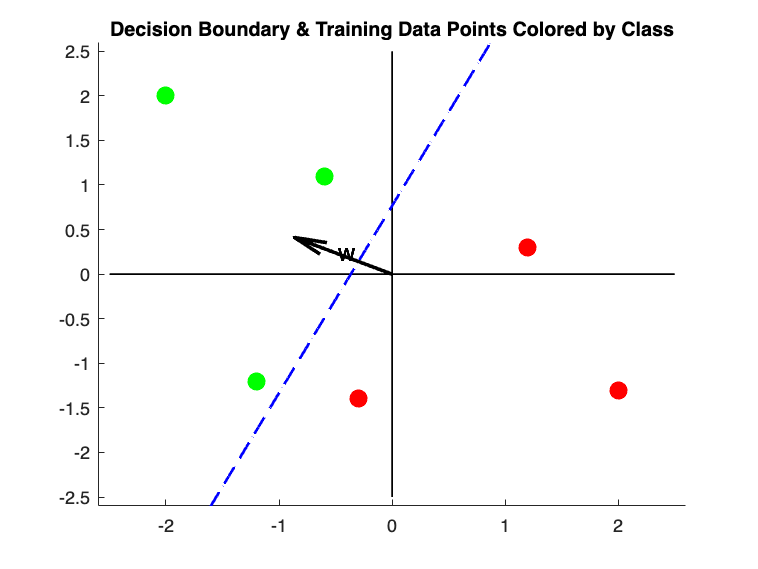

Training completed successfully in 4 epochs.


clc
clear all

% Load input data and target values
input_data = readmatrix('c2/input_p.txt');
target_data = readmatrix('c2/target_t.txt'); 

% Format data into prototypes
prototypes = cell(size(input_data, 1), 1);
for i = 1:size(input_data, 1)
    prototypes{i} = {input_data(i, :)', target_data(i, :)'};
end

% Hyperparameters
input_size = size(input_data, 2); % Number of classes
max_epochs = 100; % Maximum number of epochs
learning_rate = 0.1; % Delta value

% Create and train the ADALINE network
stop_code = 0;
ntry = 0;
number_of_retries = 1; % If training faill retry n times
c2_adaline = adalineNetwork(input_size, 'classification'); % Set for classification
while (stop_code ~= 1 && ntry < number_of_retries)
    [c2_adaline, stop_code] = c2_adaline.train(prototypes, max_epochs, learning_rate);
    ntry = ntry + 1;
end


% Save final weights and bias to files
w_file = 'c2/w.txt';
b_file = 'c2/b.txt';

% Write weights & bias to file
writematrix(c2_adaline.Weights, w_file, 'Delimiter', 'tab');
writematrix(c2_adaline.Bias, b_file, 'Delimiter', 'tab');

disp('Mode:');

Mode:


disp(c2_adaline.Mode);

classification


disp('Weights:');

Weights:


disp(c2_adaline.Weights);

   -0.9600    0.4573



disp('Bias:');

Bias:


disp(c2_adaline.Bias);

   -0.3503




c2_adaline.classify(input_data(1,:)') % -1 

ans = -1

c2_adaline.classify(input_data(2,:)') % -1 

ans = -1

c2_adaline.classify(input_data(3,:)') % -1

ans = -1

c2_adaline.classify(input_data(4,:)') % 1 

ans = 1

c2_adaline.classify(input_data(5,:)') % 1 

ans = 1

c2_adaline.classify(input_data(6,:)') % 1

ans = 1

## Example 3 classification 4 classes

#### From book P10.8

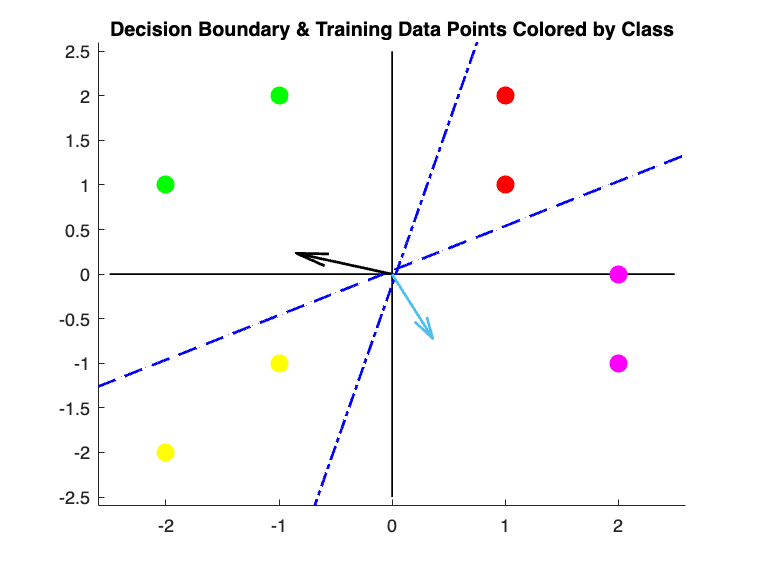

Training completed successfully in 2 epochs.


clc
clear all

% Load input data and target values
input_data = readmatrix('c3/input_p.txt');
target_data = readmatrix('c3/target_t.txt'); 

% Format data into prototypes
prototypes = cell(size(input_data, 1), 1);
for i = 1:size(input_data, 1)
    prototypes{i} = {input_data(i, :)', target_data(i, :)'};
end

% Hyperparameters
input_size = size(input_data, 2); % Number of classes
max_epochs = 100; % Maximum number of epochs
learning_rate = 0.1; % Delta value

% Create and train the ADALINE network
stop_code = 0;
ntry = 0;
number_of_retries = 1; % If training faill retry n times
c3_adaline = adalineNetwork(input_size, 'classification'); % Set for classification
while (stop_code ~= 1 && ntry < number_of_retries)
    [c3_adaline, stop_code] = c3_adaline.train(prototypes, max_epochs, learning_rate);
    ntry = ntry + 1;
end


% Save final weights and bias to files
w_file = 'c3/w.txt';
b_file = 'c3/b.txt';

% Write weights & bias to file
writematrix(c3_adaline.Weights, w_file, 'Delimiter', 'tab');
writematrix(c3_adaline.Bias, b_file, 'Delimiter', 'tab');

disp('Mode:');

Mode:


disp(c3_adaline.Mode);

classification


disp('Weights:');

Weights:


disp(c3_adaline.Weights);

   -0.9401    0.4001
    0.2599   -0.7999



disp('Bias:');

Bias:


disp(c3_adaline.Bias);

    0.0314
    0.0314




c3_adaline.classify(input_data(1,:)') % -1,-1 

ans =     -1
    -1


c3_adaline.classify(input_data(2,:)') % -1,-1 

ans =     -1
    -1


c3_adaline.classify(input_data(3,:)') % -1,1

ans =     -1
     1


c3_adaline.classify(input_data(4,:)') % -1,1 

ans =     -1
     1


c3_adaline.classify(input_data(5,:)') % 1,-1 

ans =      1
    -1


c3_adaline.classify(input_data(6,:)') % 1,-1 

ans =      1
    -1


c3_adaline.classify(input_data(7,:)') % 1,1 

ans =      1
     1


c3_adaline.classify(input_data(8,:)') % 1,1

ans =      1
     1


## Example 4 classification 4 classes

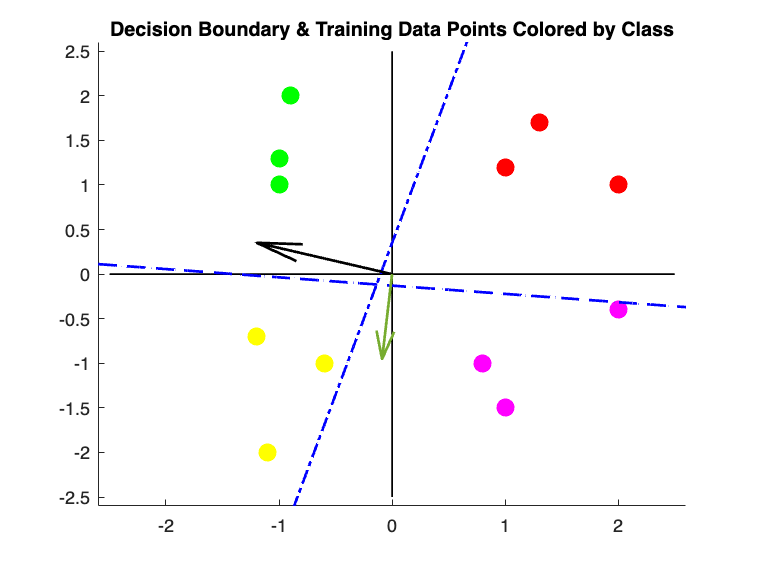

Training completed successfully in 2 epochs.


clc
clear all

% Load input data and target values
input_data = readmatrix('c4/input_p.txt');
target_data = readmatrix('c4/target_t.txt'); 

% Format data into prototypes
prototypes = cell(size(input_data, 1), 1);
for i = 1:size(input_data, 1)
    prototypes{i} = {input_data(i, :)', target_data(i, :)'};
end

% Hyperparameters
input_size = size(input_data, 2); % Number of classes
max_epochs = 100; % Maximum number of epochs
learning_rate = 0.1; % Delta value

% Create and train the ADALINE network
stop_code = 0;
ntry = 0;
number_of_retries = 1; % If training faill retry n times
c3_adaline = adalineNetwork(input_size, 'classification'); % Set for classification
while (stop_code ~= 1 && ntry < number_of_retries)
    [c3_adaline, stop_code] = c3_adaline.train(prototypes, max_epochs, learning_rate, 0.00001);
    ntry = ntry + 1;
end


% Save final weights and bias to files
w_file = 'c4/w.txt';
b_file = 'c4/b.txt';

% Write weights & bias to file
writematrix(c3_adaline.Weights, w_file, 'Delimiter', 'tab');
writematrix(c3_adaline.Bias, b_file, 'Delimiter', 'tab');

disp('Mode:');

Mode:


disp(c3_adaline.Mode);

classification


disp('Weights:');

Weights:


disp(c3_adaline.Weights);

   -1.3294   -0.0982
    0.3906   -1.0582



disp('Bias:');

Bias:


disp(c3_adaline.Bias);

   -0.1362
   -0.1362




c3_adaline.classify(input_data(1,:)') % -1,-1 

ans =     -1
    -1


c3_adaline.classify(input_data(2,:)') % -1,-1 

ans =     -1
    -1


c3_adaline.classify(input_data(3,:)') % -1,-1

ans =     -1
    -1


c3_adaline.classify(input_data(4,:)') % -1,1 

ans =     -1
     1


c3_adaline.classify(input_data(5,:)') % -1,1 

ans =     -1
     1


c3_adaline.classify(input_data(6,:)') % -1,1 

ans =     -1
     1


c3_adaline.classify(input_data(7,:)') % 1,-1 

ans =      1
    -1


c3_adaline.classify(input_data(8,:)') % 1,-1

ans =      1
    -1


c3_adaline.classify(input_data(9,:)') % 1,-1

ans =      1
    -1


c3_adaline.classify(input_data(10,:)') % 1,1

ans =      1
     1


c3_adaline.classify(input_data(11,:)') % 1,1

ans =      1
     1


c3_adaline.classify(input_data(12,:)') % 1,1

ans =      1
     1


## Example resgresion

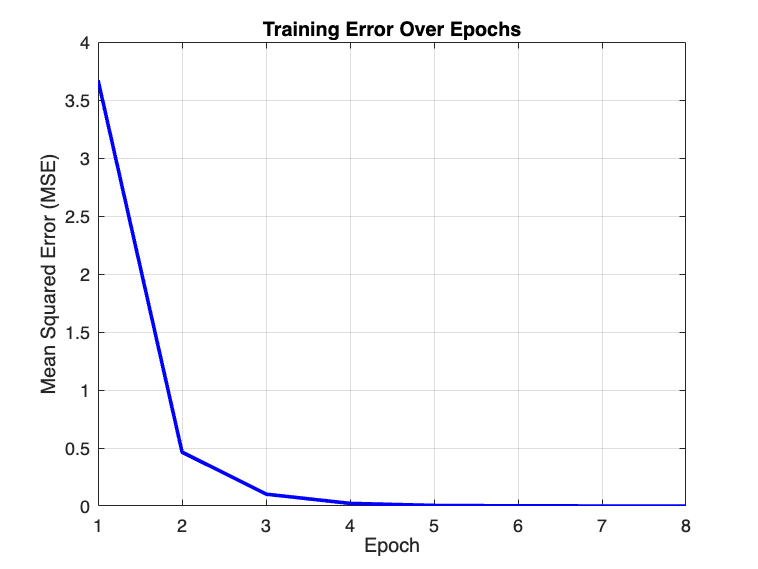

Training completed successfully in 8 epochs.


clc
clear all

% Load input data and target values
input_data = readmatrix('1/input_p.txt');
target_data = readmatrix('1/target_t.txt');

% Format data into prototypes
prototypes = cell(size(input_data, 1), 1);
for i = 1:size(input_data, 1)
    prototypes{i} = {input_data(i, :)', target_data(i, :)'}; % Column vectors
end

% Hyperparameters
input_size = size(input_data, 2); % R
max_epochs = 100; % Maximum number of epochs
learning_rate = 0.15; % Delta value
error_threshold = 0.0001; % Threshold for training error

% Create and train the ADALINE network
stop_code = 0;
ntry = 0;
number_of_retries = 1;
decoder_adaline = adalineNetwork(input_size, 'regression');
while (stop_code ~= 1 && ntry < number_of_retries)
    [decoder_adaline, stop_code] = decoder_adaline.train(prototypes, max_epochs, learning_rate, error_threshold);
    ntry = ntry + 1;
end


% Save final weights and bias to files
w_file = '1/w.txt';
b_file = '1/b.txt';

% Write weights & bias to file
writematrix(decoder_adaline.Weights, w_file, 'Delimiter', 'tab');
writematrix(decoder_adaline.Bias, b_file, 'Delimiter', 'tab');

disp('Mode:');

Mode:


disp(decoder_adaline.Mode);

regression


disp('Weights:');

Weights:


disp(decoder_adaline.Weights);

    3.9958    1.9991    1.0053



disp('Bias:');

Bias:


disp(decoder_adaline.Bias);

    4.1681




decoder_adaline.classify([1; 0; 1]) %5

ans = 5.0011

decoder_adaline.classify([0; 0; 1]) %1

ans = 1.0053

decoder_adaline.classify([1; 1; 1]) %7

ans = 7.0002